# Example raster plots showing mean responses & the effect of shuffling

d = SessManager.load_special('Mouse2022', 'events_transients');

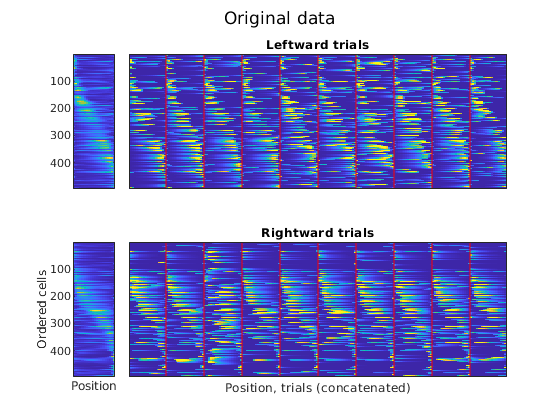

DecodeTensor.tensor_vis(d.data_tensor, d.tr_dir, @(x)x, 8);
sgtitle('Original data');
Utils.printto('events_figs/rasters', 'real_rasters.pdf');

T_shuf = DecodeTensor.shuffle_tensor_common(d.data_tensor, d.tr_dir);

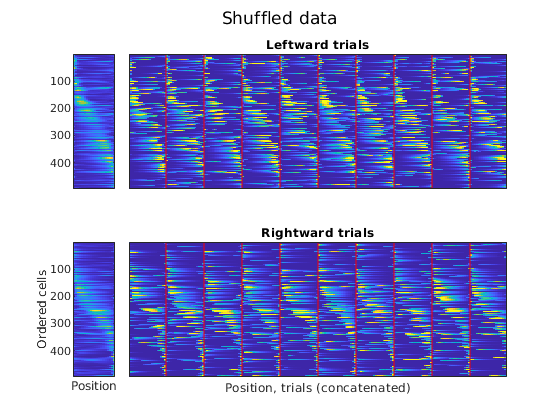

DecodeTensor.tensor_vis(T_shuf, d.tr_dir, @(x)x, 8);
sgtitle('Shuffled data');
Utils.printto('events_figs/rasters', 'shuf_rasters.pdf');